# 3. Considere 4 lancamentos de uma moeda equilibrada. Seja X a variavel aleatoria representativa do numero de coroas observados nos 4 lancamentos

## (a) Estime por simulacao a funcao massa de probabilidade pX(x) da variavel aleatoria X

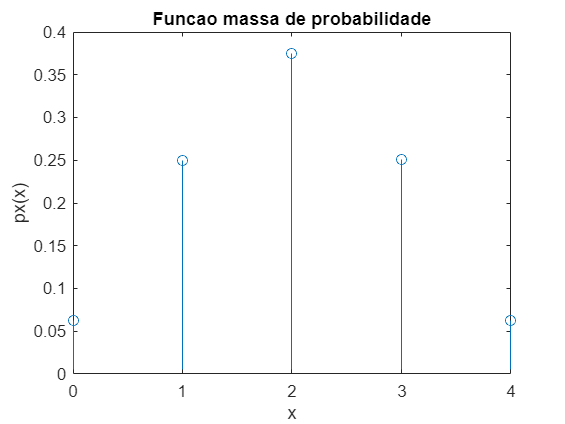

%Funcao massa de probabilidade de X:
pX = zeros(1, 5);
s = 0:4;
N = 1e5; %Numero de experiencias
p = 0.5; %Probabilidade de sair coroa
n = 4;   %numero de lancamentos por experiencia

for i=1 : 5
  k = i-1;
  pX(i) = fMassaProb(N,p,k,n);
end
stem(s,pX), xlabel('x'), ylabel('px(x)'), title('Funcao massa de probabilidade');

## (b) Estime o valor esperado, a variancia e o desvio padrao de X com base em pX(x)


%Valor esperado = somatorio de i=0 ate m de xi * P(X = xi)
E = 0;
for i=1 : 5
  E = E + (i-1) * pX(i);
end


fprintf("E[X]: %d\n",E);

E[X]: 2.003390e+00



%Variancia = E[X^2] - E^2[X]
E2 = 0;
for i=1 : 5
  E2 = E2 + (i-1)^2 * pX(i);
end

var = E2 - E^2;

fprintf("Var(X)= %d\n",var);

Var(X)= 9.975785e-01



%Desvio padrao = sqrt(var(X))
dp = sqrt(var);
fprintf("σX = %d\n",dp);

σX = 9.987885e-01
